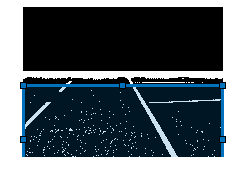

RawImg = imread("GrayImage.png");
GryImg = rgb2gray (RawImg);
bwImg = imbinarize(GryImg, 'adaptive', 'Sensitivity', 0.500000, 'ForegroundPolarity', 'bright');
imshow(bwImg)

RoadROI = drawrectangle('Position',[1 500 1275 700]);

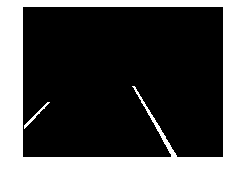

    RoiMask = uint8(RoadROI.createMask(bwImg));
    maskedImg = uint8(bwImg) .* RoiMask;

initStrel = strel('diamond',3);
erodeImg = imerode(maskedImg, initStrel);
ConnComp = bwareaopen(erodeImg , 2000);%remove components less that 1000 pixels
figure, imshow(ConnComp,[])

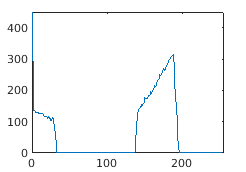


%creating plot of # of white pixels in bins on x-axis

BinSize=5;
BinStart=1;
BinNum = 1;
WhiteX = ones(1280/Binsize,1);

for Bin = 20:BinSize:1280
    WhiteX(BinNum,1) = sum(ConnComp(: ,BinStart:Bin),"all");
    BinNum = BinNum+1;
    BinStart = Bin+1;
end

plot(WhiteX)
axis([0 BinNum 0 max(WhiteX)])